# Cálculo de la Serie Exponencial de Fourier

#### Grupo 1 

Visualizamos la señal SINUSOIDAL PERIODICA ***'x'***

clc, clear;
t = 0:0.1:10;

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


x=cos(2*t)+4*sin(4*t)+1;

x =     2.0000    3.5377    4.7905    5.5535    5.6950    5.1775    4.0642    2.5099    0.7373   -0.9973   -2.4434   -3.3949   -3.7221   -3.3907   -2.4673   -1.1077    0.4679    2.0097    3.2779    4.0807    4.3038    3.9281    3.0323    1.7794    0.3902   -0.8924   -1.8428   -2.2891   -2.1411   -1.4058   -0.1861    1.3341    2.9192    4.3185    5.3060    5.7163    5.4710    4.5916    3.1969    1.4850   -0.2971   -1.8916   -3.0696   -3.6663   -3.6065   -2.9151   -1.7131   -0.1978    1.3886    2.7974


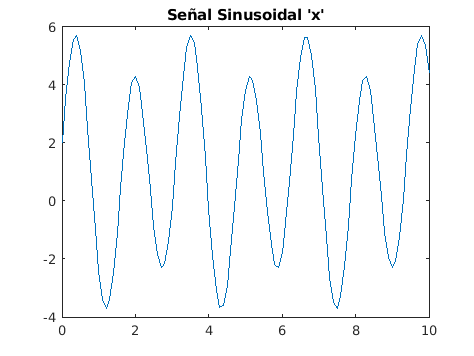

figure(1)
plot(t,x)
title("Señal Sinusoidal 'x'")

Utilizamos la variable simbolica*** 't' ***para realizar la integral de nuestra SEÑAL y obtener los Coeficientes de la Serie de Fourier.

clear; 

%Definimos las variables: Señal(x), Periodo(T),
%Frecuencia Fundamental (w0)

syms t
x=cos(2*t)+4*sin(4*t)+1

$$x = \cos\left(2\,t\right)+4\,\sin\left(4\,t\right)+1$$

T=pi;

T = 3.1416

w0=2*pi/T;

w0 = 2


% CALCULO DE COEFICIENTES PARA N=0
C0=(1/T)*int(x,t,0,T);

$$C0 = \frac{5734161139222659\,\pi }{18014398509481984}$$


% TODOS LOS COEFICIENTES:entre -10 y 10
Cn=zeros(1,21);
a=1

a = 1

for N=-10:1:10
    e=exp((-j*w0*N.*t));
    Cn(1,a)=double((1/T)*int(x*e,t,0,T));
    a=a+1;
end
Cn

Cn =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 2.0000i   0.5000 + 0.0000i   1.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 - 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


## Graficar la Magnitud y la Fase de los Coeficientes

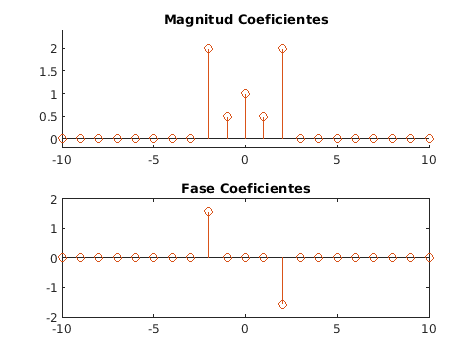

%Calculamos la magnitud y la fase de cada coeficiente.
C_mag=zeros(1,21);
C_phase=zeros(1,21);
b=1;
for i=1:1:21
    C_mag(1,b)=abs(Cn(1,i));
    C_phase(1,b)=angle(Cn(1,i));    b=b+1;
end

%GRAFICAMOS
N=-10:1:10;
figure(2)
subplot(2,1,1)
hold on
title('Magnitud Coeficientes')
ylim([-0.2 2.4])
stem(N,C_mag)
subplot(2,1,2)
stem(N,C_phase)
hold on
title('Fase Coeficientes')

## Obtener la POTENCIA PROMEDIO de la señal

potenciaInstantanea=(abs(x)).^2;
potenciaPromedio=double(int(potenciaInstantanea,t,0,T))

potenciaPromedio = 29.8451